# Multiobjective Problem with Linear Constraint

This example shows how to find the Pareto front for a multiobjective problem in the presence of a linear constraint using Matlab's gamuliobj algorithm and the Python-based MOBO algorithm within the Xopt module. Start a parallel worker pool before running (e.g. with >> parpool), else gamultiobj function call will start one automatically.

There are two objective functions and two decision variables `x`. fitnessfcn.m contains the same function for use with Xopt.

fitnessfcn = @(x)[norm(x)^2,0.5*norm(x(:)-[2;-1])^2+2];

The linear constraint is $x(1) + x(2) \le 1/2$. This constraint is also built in to fitnessfcn.m for use with Xopt.

A = [1,1];
b = 1/2;

Find the Pareto front using Matlab.

rng default % For reproducibility
opts=optimoptions('gamultiobj','UseParallel',true);
[x,fval,~,gaout] = gamultiobj(fitnessfcn,2,A,b,[],[],[],[],[],opts);

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


Find the Pareto front using Xopt (using default MOBO algorithm).

X = Xopt("fitnessfcn_xopt",2,2) ; % Define Xopt object using fitnessfcn_xopt function with 2 inputs/2 outputs
X.Optimizer = "cnsga" ; % "mobo" or "cnsga" supported
X.verbose=true; % Store output from Xopt run
X.xrange = 2 ; % allow x to take range +/-2
X.yrange = 100 ; % allow objective functions to take range +/-100
X.runopt(); % run Xopt optimizer
% Get returned points in parameter space
x1 = X.results.variables.x1(logical(X.results.feasibility));
x2 = X.results.variables.x2(logical(X.results.feasibility));
% Get objective function results (pareto front)
y1=X.results.objectives.y1(logical(X.results.feasibility));
y2=X.results.objectives.y2(logical(X.results.feasibility));
disp(X.xopt_out) % show output of Xopt run

  _   
                | |  
__  _____  _ __ | |_ 
\ \/ / _ \| '_ \| __|
 >  < (_) | |_) | |_ 
/_/\_\___/| .__/ \__|
          | |        
          |_|        

_________________________________
Parallel execution with 6 workers
Loading as YAML file: xopt_eval.yaml

            Xopt 
________________________________           
Version: 0.4.3+150.g2b35e7f.dirty
Configured: True
Config as YAML:
xopt: {output_path: null, verbose: true, algorithm: cnsga}
algorithm:
  name: cnsga
  function: xopt.cnsga.cnsga
  options: {max_generations: 400, population_size: 80, crossover_probability: 0.8,
    mutation_probability: 0.2, selection: auto, verbose: true, population: null, seed: null}
simulation:
  name: xopt_eval
  evaluate: xopt_eval.evaluate_func
  options: {matlab_f: xopt_fun, nargout: 2, verbose: true}
vocs:
  name: xopt_eval
  description: null
  simulation: xopt_eval
  templates: null
  variables:
    x1: [-2, 2]
    x2: [-2, 2]
  objectiv

Plot the constrained solution and the linear constraint using both the Matlab and Xopt optimizer outputs.

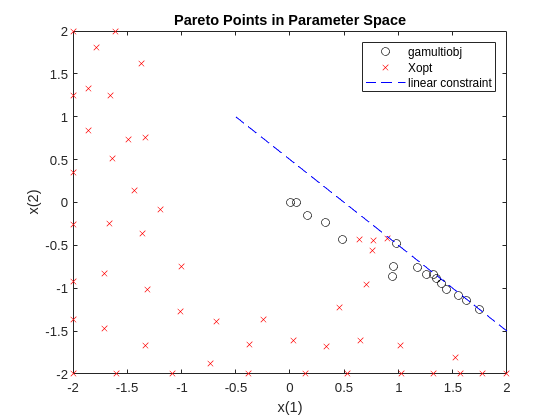

plot(x(:,1),x(:,2),'ko',x1,x2,'rx')
t = linspace(-1/2,2);
y = 1/2 - t;
hold on
plot(t,y,'b--')
hold off
xlabel('x(1)')
ylabel('x(2)')
title('Pareto Points in Parameter Space')
legend({'gamultiobj' 'Xopt' 'linear constraint'})

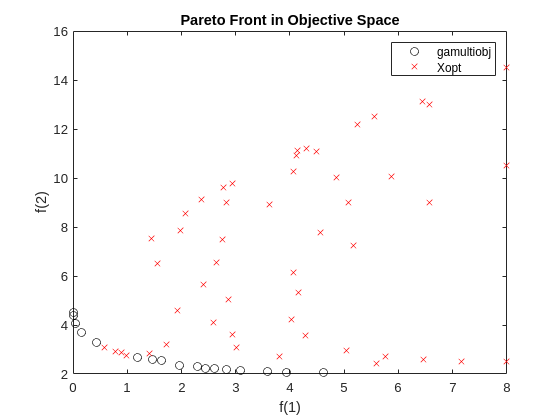

plot(fval(:,1),fval(:,2),'ko',y1,y2,'rx')
xlabel('f(1)')
ylabel('f(2)')
title('Pareto Front in Objective Space')
legend({'gamultiobj' 'Xopt'})